# Test Live Script

## Noise Performance

NOTE: *# and letters are represented by their ascii values

% Almost noise free
generate(['0','1','2','3','4','5','6','7','8','9','A','B','C','D','*','#'], 500, -100 ,'numbers/noise_free.wav');

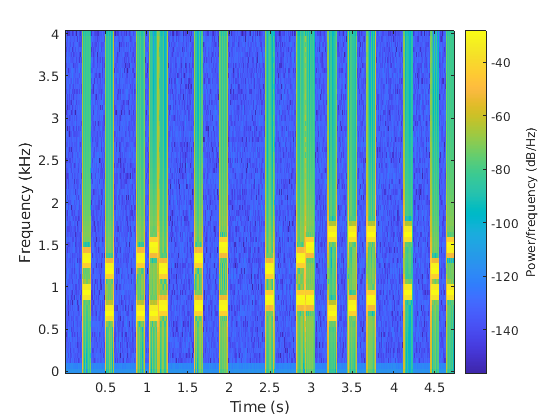

[signal, fs] = audioread("numbers/noise_free.wav");
figure(50);
spectrogram(signal,128,120,128,fs,'yaxis');

digits = detectDigits(signal,fs);
disp(digits')

     0     1     2     3     4     5     6     7     8     9    65    66    67    68    42    35



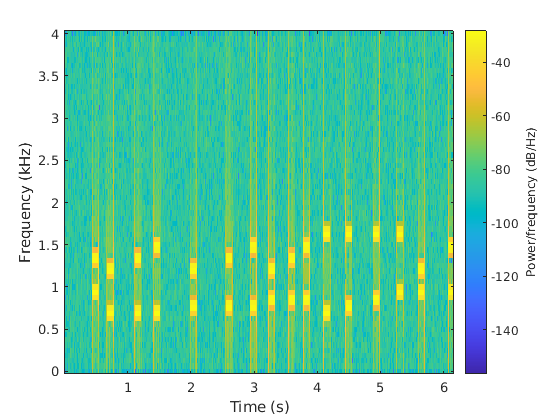

% Moderate Noise
generate(['0','1','2','3','4','5','6','7','8','9','A','B','C','D','*','#'], 500, 0 ,'numbers/noise_0dbm.wav');
[signal, fs] = audioread("numbers/noise_0dbm.wav");
figure(500);
spectrogram(signal,128,120,128,fs,'yaxis');

digits = detectDigits(signal,fs);
disp(digits')

     0     1     2     3     4     5     6     7     8     9    65    66    67    68    42    35



% High noise
generate(['0','1','2','3','4','5','6','7','8','9','A','B','C','D','*','#'], 500, 10,'numbers/noise_10dbm.wav');
[signal, fs] = audioread("numbers/noise_dbm.wav");

Error using audioread>readaudio (line 143)
The filename specified was not found in the MATLAB path.

Error in audioread (line 136)
    [y, Fs] = readaudio (filename, range, datatype);

figure(500);
spectrogram(signal,128,120,128,fs,'yaxis');
digits = detectDigits(signal,fs);
disp(digits')